# Лабораторная работа №4

Численное интегрирование методом Гаусса

Тестовый пример:

f = @(x) sin(x)./x;
n = 20;
hauss(f, [1, 3], n, false) - integral(f, 1, 3)

ans = 0

double(hauss(f, [-1, 1], n, true) - integral(f, -1, 1))

ans = 7.6547e-17

Построение зависимости ошибки от количества узлов интегрирования:

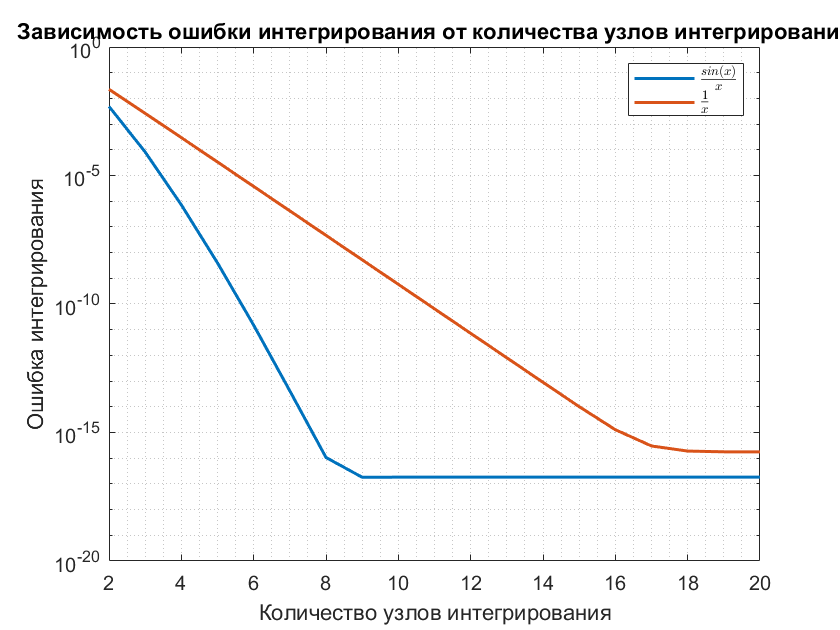

nmax = 20;
precise = true;
 
d = [1; 4];
Err = [];
for i = 1:2
    if i == 1
        f = @(x) sin(x)./x;
    else
        f = @(x) 1./x;
    end
    n = linspace(2, nmax, nmax-1);
    E = zeros(1, nmax-1);
    for j = 1:(nmax-1)
        if precise
            E(j) = abs(double(hauss(f, [d(1), d(2)], n(j), true) - integral(f, d(1), d(2))));
        else
            E(j) = abs(hauss(f, [d(1), d(2)], n(j), false) - integral(f, d(1), d(2)));
        end
    end
    Err = [Err; E];
end
figure
semilogy(n, Err(1, :), 'LineWidth', 1.5);
hold on
semilogy(n, Err(2, :), 'LineWidth', 1.5);
grid minor
xlabel('Количество узлов интегрирования')
ylabel('Ошибка интегрирования')
title("Зависимость ошибки интегрирования от количества узлов интегрирования")
legend("$\frac{sin(x)}{x}$", "$\frac{1}{x}$", 'interpreter', 'latex')

nmax = 30;
precise = false;
 
d = [1; 4];
Err = [];
% step = 2;
Err_main = [];
for step = 4:4:20
    parfor i = 1:2
        if i == 1
            f = @(x) sin(x)./x;
        else
            f = @(x) 1./x;
        end
        E = zeros(1, nmax-1);
        for k = 2:nmax
            n = linspace(d(1), d(2), k);
            I = 0;
            for j = 1:(k-1)
                I = I + double(hauss(f, [n(j), n(j+1)], step, true));
            end
            E(k-1) = abs(I - integral(f, d(1), d(2)));
        end
        Err = [Err; E];
    end
end

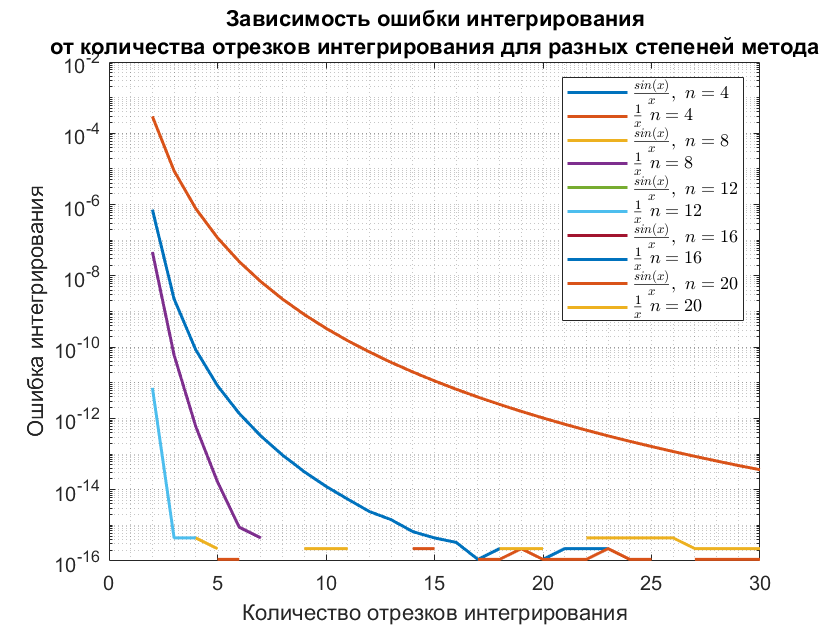

Err = Err2;

figure
semilogy(2:nmax, Err(1, :), 'LineWidth', 1.5);
hold on
semilogy(2:nmax, Err(2, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(3, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(4, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(5, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(6, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(7, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(8, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(9, :), 'LineWidth', 1.5);
semilogy(2:nmax, Err(10, :), 'LineWidth', 1.5);
grid minor
xlabel('Количество отрезков интегрирования')
ylabel('Ошибка интегрирования')
title({"Зависимость ошибки интегрирования"; "от количества отрезков интегрирования для разных степеней метода"})
legend("$\frac{sin(x)}{x},\ n=4$", "$\frac{1}{x}\ n=4$", ...
       "$\frac{sin(x)}{x},\ n=8$", "$\frac{1}{x}\ n=8$", ...
       "$\frac{sin(x)}{x},\ n=12$", "$\frac{1}{x}\ n=12$", ...
       "$\frac{sin(x)}{x},\ n=16$", "$\frac{1}{x}\ n=16$", ...
       "$\frac{sin(x)}{x},\ n=20$", "$\frac{1}{x}\ n=20$", 'interpreter', 'latex')

Построение зависимости ошибки от параметра:

nmax = 20;
precise = true;
 
Err = [];
for i = 1:2
    if i == 1
        f = @(x) sin(x)./x;
    else
        f = @(x) 1./x;
    end
    a = logspace(-30, 0, 100);
    E = zeros(1, max(size(a)));
    for j = 1:max(size(a))
        if precise
            E(j) = abs(double(hauss(f, [a(j), 4], nmax, true) - integral(f, a(j), 4)));
        else
            E(j) = abs(hauss(f, [a(j), 4], nmax, false) - integral(f, a(j), 4));
        end
    end
    Err = [Err; E];
end

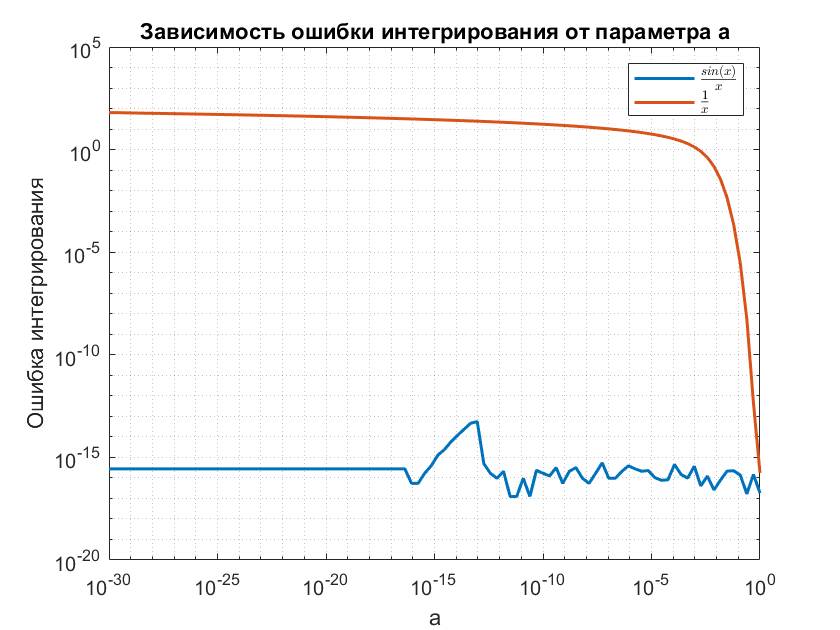

figure
loglog(a, Err(1, :), 'LineWidth', 1.5);
hold on
loglog(a, Err(2, :), 'LineWidth', 1.5);
grid minor
xlabel('a')
ylabel('Ошибка интегрирования')
title("Зависимость ошибки интегрирования от параметра a")
legend("$\frac{sin(x)}{x}$", "$\frac{1}{x}$", 'interpreter', 'latex')

function S = hauss(f, d, n, precise)
    [roots, orr] = get_l_roots(n, d);
    der = get_l_diff(n);
    S = 0;
    for i = 1:max(size(roots))
        A = 2/((1-orr(i).^2)*(der(orr(i)).^2));
        if roots(i) ~= 0
            S = S + A*f(roots(i));
        else
            S = S + A*f(1e-300);
        end
    end
    S = S*(d(2) - d(1))/2;
    if ~precise
        S = double(S);
    end
end

function [roots, orr] = get_l_roots(n, d)
    syms x;
    roots = sort(vpasolve(legendreP(n,x) == 0));
    orr = roots;
    for i = 1:max(size(roots))
        roots(i) = (d(2)+d(1))/2 + roots(i)*(d(2)-d(1))/2;
    end
end

function der = get_l_diff(n)
    syms x der;
    expr = legendreP(n,x);
    der(x) = diff(expr, x);
end